clear all, clc

## Setup paths

videoPath = 'test_clip.mp4';
centroidModelPath = 'models/centroids.200823_193403.UNet';
topdownModelPath = 'models/topdown.200823_204048.UNet';

## Initialize

% Load models and configs.
centroidConfig = loadJobConfig(centroidModelPath);
inputScale = centroidConfig.data.preprocessing.input_scaling;

topdownConfig = loadJobConfig(topdownModelPath);
bboxSize = [topdownConfig.data.instance_cropping.crop_size topdownConfig.data.instance_cropping.crop_size];

centroidModel = loadModel(centroidModelPath);

topdownModel = loadModel(topdownModelPath);


% Open video.
vr = VideoReader(videoPath);

## Run inference on video frames.

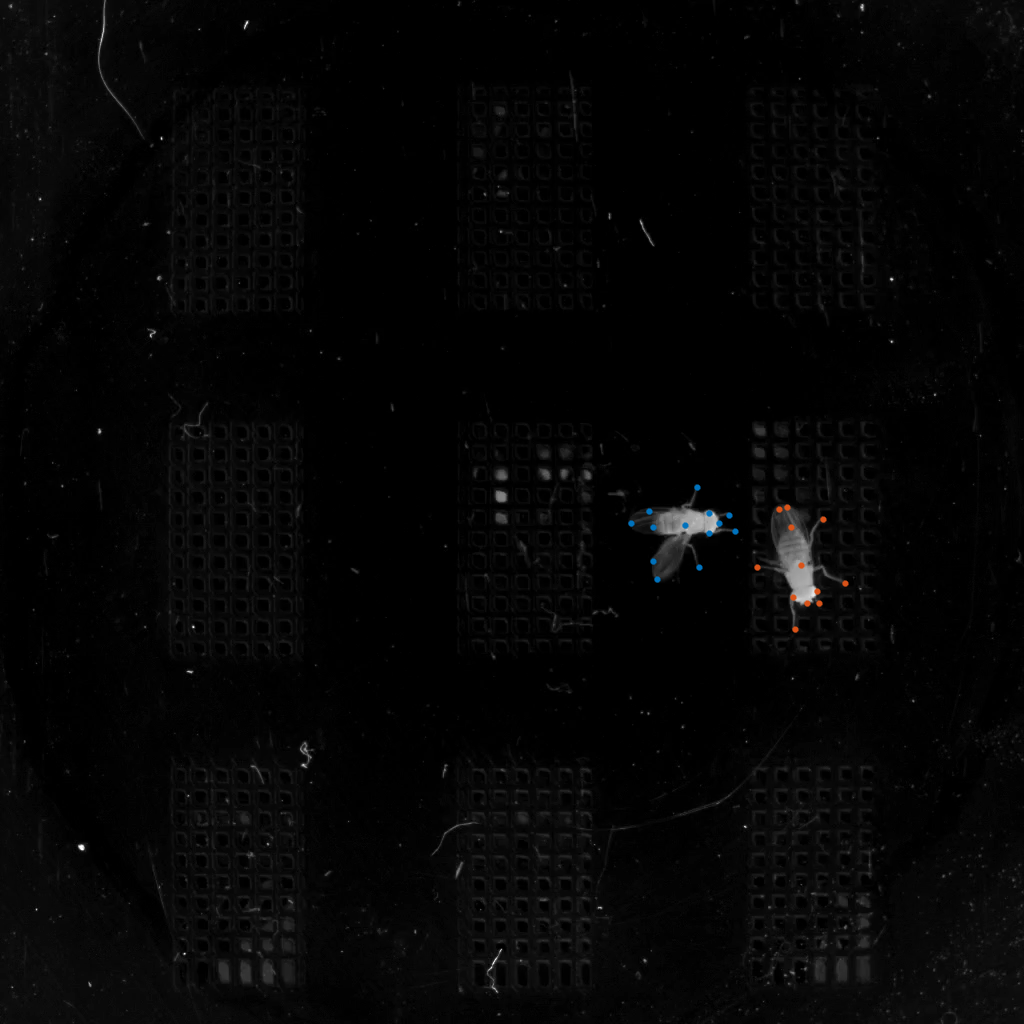

frameIdx = 1;

% Load image.
img = rgb2gray(vr.read(frameIdx));
img = single(img) / 255;

% Find centroids.
centroidConfmaps = centroidModel.predict(imresize(img, inputScale));
centroidPeaks = impeaksnms(centroidConfmaps, 0.3);
centroidPeaks = centroidPeaks / inputScale;
centroidPeaks = centroidPeaks * centroidConfig.model.heads.centroid.output_stride;

% Predict pose on crops.
crops = arrayfun(@(i)centerCrop(img,centroidPeaks(i,1),centroidPeaks(i,2),bboxSize), 1:size(centroidPeaks,1), 'UniformOutput',false);
cropConfmaps = cellfun(@(x)topdownModel.predict(x), crops, 'UniformOutput',false);
cropPeaks = cellcat(cellfun(@findAllPeaks, cropConfmaps, 'UniformOutput',false),3);
cropPeaks = cropPeaks * topdownConfig.model.heads.centered_instance.output_stride;
allPeaks = cropPeaks + permute(centroidPeaks, [3 2 1]) - (bboxSize * 0.5);

% Visualize
vizPeaks(img, allPeaks)

## Helper functions

function net = loadModel(modelPath)
    if ~endsWith(modelPath, '.h5')
        modelPath = fullfile(modelPath, 'best_model.h5');
    end
    lgraph = importKerasLayers(modelPath,'ImportWeights',true);
    outLayer = regressionLayer('Name','output');
    lgraph = replaceLayer(lgraph, lgraph.Layers(end).Name, outLayer);
    net = assembleNetwork(lgraph);
end
function jobConfig = loadJobConfig(modelPath)
    jobConfig = jsondecode(fileread(fullfile(modelPath, 'training_config.json')));
end
function crop = centerCrop(img, x, y, bboxSize)
    R = imref2d(bboxSize, [x - bboxSize(1)/2, x + bboxSize(1)/2], [y - bboxSize(1)/2, y + bboxSize(2)/2]);
    crop = imwarp(img,affine2d(),'OutputView',R);
end
function peaks = findAllPeaks(confmaps, minThresh)
    if nargin < 2; minThresh = 0.2; end
    C = size(confmaps,3);
    peaks = NaN(C, 2);
    for c = 1:C
        [point, val] = imargmax(confmaps(:,:,c));
        if val >= minThresh
            peaks(c,:) = point;
        end
    end
end
function vizPeaks(img, allPeaks)
    figure
    imshow(img, 'Border', 'tight'), hold on
    for i = 1:size(allPeaks,3)
        plot(allPeaks(:,1,i),allPeaks(:,2,i),'.','MarkerSize',10)
    end
end